# Ising Model 2D

## Import data

numOfIterations=500;
numOfTemps=12;

it=numOfTemps*numOfIterations;

[N1, temp1, mag1, en1, ~, ~] = importfile("../../../cmake-build-release/bin/IsingResults.tsv",1,it);
[N2, temp2, mag2, en2, ~, ~] = importfile("../../../cmake-build-release/bin/IsingResults.tsv",it+1,2*it);
[N3, temp3, mag3, en3, ~, ~] = importfile("../../../cmake-build-release/bin/IsingResults.tsv",2*it+1,3*it);
[N4, temp4, mag4, en4, ~, ~] = importfile("../../../cmake-build-release/bin/IsingResults.tsv",3*it+1,4*it);

Energy vs temperature

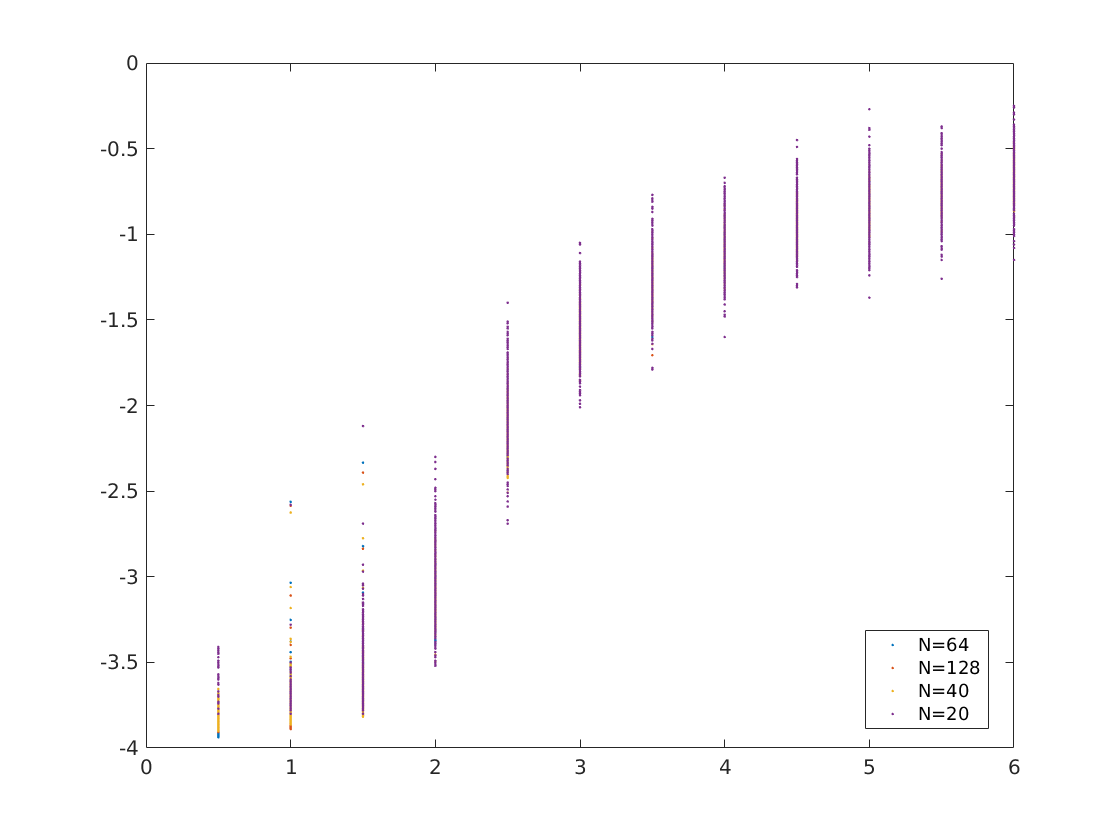

figure(1)
plot(temp1,en1,'.',"DisplayName","N="+N1(1))
hold on
plot(temp2,en2,'.',"DisplayName","N="+N2)
plot(temp3,en3,'.',"DisplayName","N="+N3)
plot(temp4,en4,'.',"DisplayName","N="+N4)
legend('Location',"best")

Magnetization vs temperature

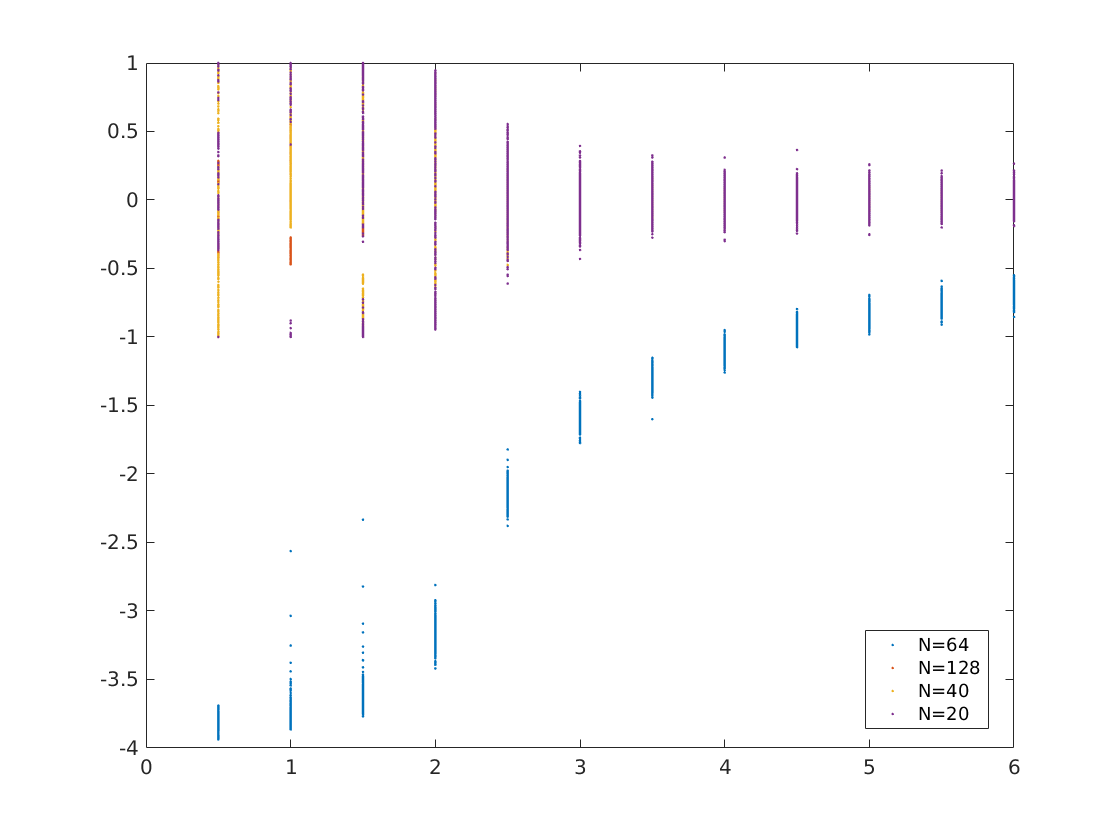

figure(2)
plot(temp1,en1,'.',"DisplayName","N="+N1)
hold on
plot(temp2,mag2,'.',"DisplayName","N="+N2)
plot(temp3,mag3,'.',"DisplayName","N="+N3)
plot(temp4,mag4,'.',"DisplayName","N="+N4)
legend('Location',"best")